# Script for calculating current control mode parameters:

load ('CNC110X69-5.mat');
load ('Samsung_30Q_18650_pack.mat');

% Step input settings:
Sim_time = 20 * 10^-3; % [ms]
Step_time = 2 * 10^-3; % [ms]
Ir01 = 0.1;
Ir02 = pv_data.Impp;
Ramp = 1;

% Switching frequency:
f = 1 * 10^5; % [Hz]
T = 1/f;

% Maximum duty cycle that can be achieved:
D_max = 1 - pv_data.Vmpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
R = 50;
Rt = 1*10^5;
RL = 10 * 10^-3;
L = 1000 * 10^-6;
Rt = 1*10^5;
Cu = 100 * 10^-6;
Ci = 3760 * 10^-6;
Ru = Bat.Ru;
Cbat = Bat.Qbat_tot/(Bat.Ubat_charged - Bat.Ubat_cut_off);

% Lomna frekv. izlaznog RC kruga:
f_RC = 1/(2*pi*R*Ci)

f_RC = 0.8466

## Get Characteristic input resistance of PV source:

if ~(exist("solar_out"))
    solar_out = sim("Solar.slx");
end

R_pv_sim = solar_out.get("Rpv_sim").Data;
U_pv_sim = solar_out.get("Upv_sim").Data;
I_pv_sim = solar_out.get("Ipv_sim").Data;

for i = 1:length(R_pv_sim)
    if R_pv_sim(i) == inf
        R_pv_sim(i) = 1000;
    end
end

## Steady state (point of maximum power):

Ipv0 = pv_data.Impp;
Ir0 = Ipv0;
Upv0 = pv_data.Vmpp;
Ubat0 = Bat.Ubat_nom;
Upvmin = Bat.Ubat_charged - 0.9*Bat.Ubat_charged

Upvmin = 0.8400

m0 = (Bat.Ubat_charged-2*Upvmin)/(2*L);

% CCM operating point (no compensation):
Im0_ccm = Ir0-(T*Upv0)/(L*Ubat0)*(Ubat0 - Upv0)

Im0_ccm = 0.2347

Lmin = (T*Upv0)/(Ubat0*Ir0)*(Ubat0-Upv0)

Lmin = 6.1111e-05

ro_ccm = Ubat0/Upv0+(L/T)*(Ubat0/Upv0^2)*(Im0_ccm-Ir0)

ro_ccm = 1.0000


% CCM operating point (with compensation):
Im0_ccm_m = Ir0-T/L*(Upv0+m0*L)/Ubat0*(Ubat0-Upv0)

Im0_ccm_m = 0.2245

Lmin_m = T*(Upv0+m0*L)/(Ir0*Ubat0)*(Ubat0-Upv0)

Lmin_m = 1.0218e-04

ro_ccm_m = 1/2*(1+L/T*(Im0_ccm_m-m0*L)/(Upv0+m0*L))+1/2*((-1/T*L/(Upv0+m0*L))*(Ir0-T/L*(Ubat0-Upv0)+(Ir0-Im0_ccm_m)/(Upv0+m0*L)*(Ubat0-Upv0-m0*L)))+1/2*Ubat0/(Upv0+m0*L)*(1-L/T*(Ir0-Im0_ccm_m)/(Upv0+m0*L))

ro_ccm_m = -19.2967


% DCM:
ro_dcm = L/T*(Ubat0*Upv0)/(Ubat0-Upv0)*(Ir0)/(Upv0-m0*L)^2;

% CCM Average diode current:
ID1_ccm = 1/2*(Ir0+Im0_ccm-T/L*(Ubat0-Upv0)+Ubat0/Upv0*(Ir0-Im0_ccm)-L/T*(Ir0^2-Im0_ccm^2)/Upv0+(Ir0-Im0_ccm)/Upv0*(Ubat0-Upv0)-L/T*Ubat0/Upv0^2*(Ir0-Im0_ccm)^2)

ID1_ccm = 0.1683

## CCM tf's with no compensation:

% Im i iD:
k4 = 1/T*Ubat0/Upv0;
k5 = -1/T*Ubat0/Upv0;
k6 = 1/L-1/T*Ubat0/(Upv0^2)*(Ir0-Im0_ccm);
k7 = (Ir0-Im0_ccm)/(T*Upv0)-1/L;
k8 = Ubat0/Upv0-(L*Ir0)/(T*Upv0)*(1+Ubat0/Upv0)+(L*Ubat0)/(T*Upv0^2)*Im0_ccm;
k9 = 1-Ubat0/Upv0+(L*Im0_ccm)/(T*Upv0)*(1-Ubat0/Upv0)+(L*Ubat0)/(T*Upv0^2)*Ir0;
k10 = (T)/(2*L)-((Ubat0)/(Upv0^2))*(Ir0-Im0_ccm)+(L)/(2*T)*(Ir0^2-Im0_ccm^2)/(Upv0^2)+(L*Ubat0)/(T*Upv0^3)*((Ir0-Im0_ccm)^2);
k11 = -(T)/(2*L)+(Ir0-Im0_ccm)/Upv0-(L)/(2*T)*((Ir0-Im0_ccm)^2)/(Upv0^2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%% Cbat -> inf %%%%%%%%%%%%%%%%%%%%%%%%%
k12 = Ci*Rt*Ru;
k13 = Ru+Rt-Rt*Ru*k11-Ci*Rt*Ru*k5;
k14 = Rt*Ru*k5*k11-Rt*Ru*k7*k9-Rt*k5-Ru*k5;
% Ir:
k15 = Rt*Ru*k8;
k16 = Rt*Ru*k4*k9-Rt*Ru*k5*k8;
% Upv:
k17 = Rt*Ru*k10;
k18 = Rt*Ru*k6*k9-Rt*Ru*k5*k10;

Tn = sqrt(k12/k14);
zeta = 1/2*k13/(sqrt(k14*k12))

zeta = 1.0146

Tz1 = -k15/k16

Tz1 = 4.0000e-05

Tz2 = k17/k18

Tz2 = 3.3234e-06

K1 = k16/k14;
K2 = k18/k14;
Tp1 = Tn/(zeta-sqrt(zeta^2-1))

Tp1 = 9.7740e-06

Tp2 = Tn/(zeta+sqrt(zeta^2-1))

Tp2 = 6.9454e-06

%%%%%%%%%%%%%%%%%%%%%%% Cbat -> inf %%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%% FULL %%%%%%%%%%%%%%%%%%%%%%%%%%%%
k90 = -Cbat*Ci*Rt*Ru;
k91 = Cbat*Rt*Ru*k11-Cbat*Ru-Ci*Rt-Cbat*Rt+Cbat*Ci*Rt*Ru*k5;
k92 = Rt*k11+Cbat*Rt*k5+Cbat*Ru*k5+Ci*Rt*k5-Cbat*Rt*Ru*k5*k11+Cbat*Rt*Ru*k7*k9-1;
k93 = k5-Rt*k5*k11+Rt*k7*k9;
% Ir:
k94 = -Cbat*Rt*Ru*k8;
k95 = Cbat*Rt*Ru*k5*k8-Cbat*Rt*Ru*k4*k9-Rt*k8;
k96 = Rt*k5*k8-Rt*k4*k9;
%Upv:
k97 = -Cbat*Rt*Ru*k10;
k98 = Cbat*Rt*Ru*k5*k10-Rt*k10-Cbat*Rt*Ru*k6*k9;
k99 = Rt*k5*k10-Rt*k6*k9;
%%%%%%%%%%%%%%%%%%%%%%%%%%% FULL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% G_Ubat_Ir_N = tf([k15, k16], [k12, k13, k14]);
% G_Ubat_Upv_N = tf([k17, k18], [k12, k13, k14]);

G_Ubat_Ir_full = tf([k94, k95, k96], [k90, k91, k92, k93]);
G_Ubat_Upv_full = tf([k97, k98, k99], [k90, k91, k92, k93]);

G_Ubat_Ir = tf([-Tz1*K1, K1], [(Tp1*Tp2), (Tp1+Tp2), 1]);
G_Ubat_Upv = tf([Tz2*K2, K2], [(Tp1*Tp2), (Tp1+Tp2), 1]);

G_Ubat_Ir_nozero = tf(K1, [(Tp1*Tp2), (Tp1+Tp2), 1]);
G_Ubat_Upv_nozero = tf(K2, [(Tp1*Tp2), (Tp1+Tp2), 1]);

G_Ubat_Ir_red = tf(K1, [Tp1, 1]);
G_Ubat_Upv_red = tf(K2, [Tp1, 1]);

G_Upv_IL = tf(-1, [Cu, Ipv0/Upv0]);

% Utjecaj nula:
Tp1/(-Tz1)

ans = -0.2443

Tp1/Tz2

ans = 2.9410


% Utjecaj polova: 
Tp1/Tp2

ans = 1.4072

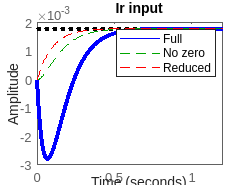


figure();
grid on;
step(G_Ubat_Ir, "b");
set(findall(gcf,'Type','Line'), 'LineWidth', 3);
hold on;
step(G_Ubat_Ir_nozero, "--g");
step(G_Ubat_Ir_red, "--r");
hold off;
legend("Full", "No zero", "Reduced");
title("Ir input");

% 
% figure();
% grid on;
% step(G_Ubat_Upv, "b");
% set(findall(gcf,'Type','Line'), 'LineWidth', 3);
% hold on;
% step(G_Ubat_Upv_nozero, "--g")
% step(G_Ubat_Upv_red, "--r");
% hold off;
% legend("Full", "No zero", "Reduced");
% title("Upv input");

% TOTAL RESPONSE:

G_Ubat_Ir_Cbat = G_Ubat_Ir_full + ro_ccm*G_Upv_IL*G_Ubat_Upv_full;
G_Ubat_Ir_noCbat = G_Ubat_Ir + ro_ccm*G_Upv_IL*G_Ubat_Upv;

% figure();
% grid on;
% step(G_Ubat_Ir_Cbat, 'b');
% set(findall(gcf,'Type','Line'), 'LineWidth', 3);
% hold on;
% step(G_Ubat_Ir_noCbat, 'r--');
% hold off;
% legend("Full", "no Cbat");
% ylabel("Ubat");
% title("Total response")

##  CCM tf's (with compensation):

%%%%%%%%%%%%%%%%%%%%%%%% Im i iD %%%%%%%%%%%%%%%%%%%%%%%%%%%%
k19 = 1/T*Ubat0/(Upv0+m0*L);
k20 = -1/T*(Ubat0)/(Upv0+m0*L);
k21 = 1/L-1/T*(Ubat0)/((Upv0+m0*L)^2)*(Ir0-Im0_ccm_m);
k22 = 1/T*(Ir0-Im0_ccm_m)/(Upv0+m0*L)-1/L;
k23 = 1-L/T*(2*(Ir0-Im0_ccm_m))/(Upv0+m0*L)+(Ubat0-Upv0-m0*L)/(Upv0+m0*L)-L/T*(Ubat0-Upv0-2*m0*L)/((Upv0+m0*L)^2)*(Ir0-Im0_ccm_m);
k24 = L/T*Ir0/(Upv0+m0*L)-(Ubat0-Upv0-m0*L)/(Upv0+m0*L)+L/T*(Ubat0-Upv0-2*m0*L)/((Upv0+m0*L)^2)*(Ir0-Im0_ccm_m);
k25 = T/(2*L)+(Ir0-Im0_ccm_m)/((Upv0+m0*L)^2)*(L/T*Ir0-Ubat0)+L/(2*T)*((Ir0-Im0_ccm_m)^2)*(2*Ubat0-Upv0-3*m0*L)/((Upv0+m0*L)^3);
k26 = -T/(2*L)+(Ir0-Im0_ccm_m)/(Upv0+m0*L)-L/(2*T)*((Ir0-Im0_ccm_m)^2)/((Upv0+m0*L)^2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%% Cbat -> inf %%%%%%%%%%%%%%%%%%%%%%%%%
k27 = Ci*Rt*Ru;
k28 = Rt+Ru-Rt*Ru*k26-Ci*Rt*Ru*k20;
k29 = Rt*Ru*k20*k26-Ru*k20-Rt*k20-Rt*Ru*k22*k24;
% Ir:
k30 = Rt*Ru*k23;
k31 = Rt*Ru*k19*k24-Rt*Ru*k20*k23;
% Upv:
k32 = Rt*Ru*k25;
k33 = Rt*Ru*k21*k24-Rt*Ru*k20*k25;

Tn_m = sqrt(k27/k29);
zeta_m = 1/2*k28/(sqrt(k29*k27))

zeta_m = 1.0037

Tz1_m = -k30/k31

Tz1_m = -1.4271e-06

Tz2_m = k32/k33

Tz2_m = 3.6157e-06

K1_m = k31/k29;
K2_m = k33/k29;
Tp1_m = Tn_m/(zeta_m-sqrt(zeta_m^2-1))

Tp1_m = 1.1607e-05

Tp2_m = Tn_m/(zeta_m+sqrt(zeta_m^2-1))

Tp2_m = 9.7792e-06

Tp1_m/Tp2_m

ans = 1.1869

%%%%%%%%%%%%%%%%%%%%%%% Cbat -> inf %%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%% FULL %%%%%%%%%%%%%%%%%%%%%%%%%%%%
k80 = Cbat*Ci*Rt*Ru;
k81 = Cbat*Rt+Cbat*Ru+Ci*Rt-Cbat*Rt*Ru*k26-Cbat*Ci*Rt*Ru*k20;
k82 = Cbat*Rt*Ru*k20*k26-Cbat*Rt*k20-Cbat*Ru*k20-Ci*Rt*k20-Rt*k26-Cbat*Rt*Ru*k22*k24+1;
k83 = -k20+Rt*k20*k26-Rt*k22*k24;
% Ir:
k84 = Cbat*Rt*Ru*k23;
k85 = Rt*k23+Cbat*Rt*Ru*k19*k24-Cbat*Rt*Ru*k20*k23;
k86 = Rt*k19*k24-Rt*k20*k23;
%Upv:
k87 = Cbat*Rt*Ru*k25;
k88 = Rt*k25-Cbat*Rt*Ru*k20*k25+Cbat*Rt*Ru*k21*k24;
k89 = -Rt*k20*k25+Rt*k21*k24;
%%%%%%%%%%%%%%%%%%%%%%%%%%% FULL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

G_Ubat_Ir_full_m = tf([k84, k85, k86], [k80, k81, k82, k83]);
G_Ubat_Upv_full_m = tf([k87, k88, k89], [k80, k81, k82, k83]);

G_Ubat_Ir_m = tf([-K1_m*Tz1_m, K1_m], [(Tp1_m*Tp2_m), (Tp1_m+Tp2_m), 1]);
G_Ubat_Upv_m = tf([K2_m*Tz2_m, K2_m], [(Tp1_m*Tp2_m), (Tp1_m+Tp2_m), 1]);

G_Ubat_Ir_nozero_m = tf(K1_m, [(Tp1_m*Tp2_m), (Tp1_m+Tp2_m), 1]);
G_Ubat_Upv_nozero_m = tf(K2_m, [(Tp1_m*Tp2_m), (Tp1_m+Tp2_m), 1]);

G_Ubat_Ir_red_m = tf(K1_m, [Tp1_m, 1]);
G_Ubat_Upv_red_m = tf(K2_m, [Tp1_m, 1]);

G_Upv_IL = tf(-1, [Cu, Ipv0/Upv0]);

% Utjecaj nula:
Tp1_m/(-Tz1_m)

ans = 8.1331

Tp1_m/Tz2_m

ans = 3.2100


% Utjecaj polova:
Tp1_m/Tp2_m

ans = 1.1869

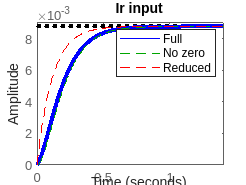


figure();
grid on;
step(G_Ubat_Ir_m, "b");
set(findall(gcf,'Type','Line'), 'LineWidth', 3);
hold on;
step(G_Ubat_Ir_nozero_m, "--g");
step(G_Ubat_Ir_red_m, "--r");
hold off;
legend("Full", "No zero", "Reduced");
title("Ir input");


% figure();
% grid on;
% step(G_Ubat_Upv_m, "b");
% set(findall(gcf,'Type','Line'), 'LineWidth', 3);
% hold on;
% step(G_Ubat_Upv_nozero_m, "--g")
% step(G_Ubat_Upv_red_m, "--r");
% hold off;
% legend("Full", "No zero", "Reduced");
% title("Upv input");

## DCM tf's:

% Even though it is not necessary, compensation needs to be included
% to maintain stability during switching between CCM and DCM modes!
k34 = L/T*(Upv0^2*Ir0)/((Ubat0-Upv0)*(Upv0+m0*L)^2);
k35 = (L*Upv0*Ir0^2)/(2*T)*(Upv0^2+m0*L*(2*Ubat0-Upv0))/((Ubat0-Upv0)^2*(Upv0+m0*L)^3);
k36 = -L/(2*T)*(Ir0^2*Upv0^2)/((Ubat0-Upv0)^2*(Upv0+m0*L)^2);
k37 = Ci*Rt*Ru;
k38 = Ru+Rt-Rt*Ru*k36;
k39 = Rt*Ru*k34;
k40 = Rt*Ru*k35;

K1_dcm = k39/k38;
K2_dcm = k40/k38;
Tn_dcm = k37/k38;

G_Ubat_Ir_DCM = tf(K1_dcm, [Tn_dcm, 1]);
G_Ubat_Upv_DCM = tf(K2_dcm, [Tn_dcm, 1]);

## Full system

Tp1_ccm = Tp1_m;
Tp2_ccm = Cu*Upv0/Ipv0;
Tz_ccm = (K1_m*Tp2_ccm)/(K1_m-ro_ccm_m*K2_m*Upv0/Ipv0);
K_ccm = K1_m-ro_ccm_m*K2_m*Upv0/Ipv0;

Tp1_dcm = Tn_dcm;
Tp2_dcm = Tp2_ccm;
Tz_dcm = (K1_dcm*Tp2_dcm)/(K1_dcm-ro_dcm*K2_dcm*Upv0/Ipv0);
K_dcm = K1_dcm-ro_dcm*K2_dcm*Upv0/Ipv0;

G_sys_ccm = tf([K_ccm*Tz_ccm, K_ccm], [Tp1_ccm*Tp2_ccm, (Tp1_ccm+Tp2_ccm), 1]);
G_sys_dcm = tf([K_dcm*Tz_dcm, K_dcm], [Tp1_dcm*Tp2_dcm, (Tp1_dcm+Tp2_dcm), 1]);

figure();
step(G_sys_ccm);

figure();
step(G_sys_dcm);

% CCM -> DCM:
cond = (T)/(Ubat0*L)*((Ubat0-Upv0)*(Upv0+m0*L))

## Frequency analysis:

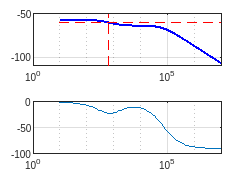

% System bode plot:

% Cutoof freq:
A = -1/2*Tp1_ccm^2*Tp2_ccm^2;
B = Tz_ccm^2-1/2*Tp1_ccm^2-1/2*Tp2_ccm^2;
C = 1/2;
omega_c = sqrt((-B-sqrt(B^2-4*A*C))/(2*A));

[ccm_mag, ccm_phase, ccm_w] = bode(G_sys_ccm);
ccm_mag = 20*log10(squeeze(ccm_mag));
ccm_phase = squeeze(ccm_phase);
ccm_w = squeeze(ccm_w);

tiledlayout(2, 1);
title("CCM system bod eplot");

nexttile
ylabel("Amplituda [dB]");
semilogx(ccm_w, ccm_mag, 'b', 'LineWidth', 1.5);
hold on;
grid on;
plot([omega_c, omega_c], ylim, "--r");
plot(xlim, [ccm_mag(1)-3, ccm_mag(1)-3], "--r");
% hold off;

nexttile
ylabel("faza [deg]");
xlabel("Frekvencija [rad/s]");
semilogx(ccm_w, ccm_phase);
grid on;

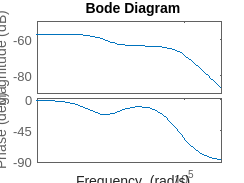


figure();
bode(G_sys_ccm)

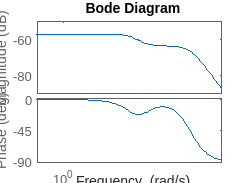

% Full system open loop:
KR = 1;
Ti = 1;
GR = tf([KR*Ti, KR], [Ti, 1]);

figure();
grid on;
hold on;
title("CCM full system open loop bode plot");
bode(G_sys_ccm*GR);

## Nonlinear vs linear (model comparison):

% Simulink step response:
% if ~(exist("nonlin")) || ~(exist("lin"))
%     nonlin = sim("Nealinearni_realwni.slx");
%     lin = sim("Strujni_nacin.slx");
% end

nonlin = sim("Nealinearni_realni.slx");

Error due to multiple causes.

Caused by:
    Error using Parametri_strujni
    Error evaluating parameter 'Capacitance' in 'Nealinearni_realni/DC boost pretvarac/Cbat'
        Error using Parametri_strujni
        Unrecognized function or variable 'Cbat'.
            Error using Parametri_strujni
            Variable 'Cbat' does not exist. 
    Error using 

lin = sim("Strujni_nacin.slx");

figure();
title("Linear vs nonlinear")
plot(nonlin.get("Ubat").Time, nonlin.get("Ubat").Data, "b", 'LineWidth', 3.0);
hold on;
plot(lin.get("Ubat").Time, lin.get("Ubat").Data, "--g", 'LineWidth', 1.5);
plot(lin.get("Ubat_m").Time, lin.get("Ubat_m").Data, "--r", 'LineWidth', 1.5);
ylim([7.199, 7.201]);
xlim([0.001, Sim_time]);
grid on;
hold off;
legend("Nelinearni", "Bez kompenzacije", "S kompenzacijom");

## Iscezavanje:

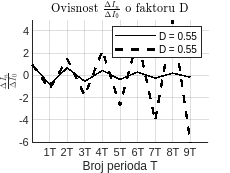

% D = linspace(0.45, 0.55, 0.5);
D = [0.45, 0.55];
n = linspace(0, 9, 10);
for i = 1:length(D)
    for j = 1:length(n)
        y(j, i) = (-D(i)/(1-D(i)))^n(j);
    end
end

str = '$\frac{\Delta I_n}{\Delta I_0}$';

figure()
grid on;
hold on;
plot(n, y(:, 1), 'k-', 'LineWidth', 1.2, 'DisplayName', sprintf('D = %.2f', D(i)));
plot(n, y(:, 2), 'k--', 'LineWidth', 1.8, 'DisplayName', sprintf('D = %.2f', D(i)));
hold off;
legend('show','Location','northeast');
xticks(n(2:end));                 % Skip n = 0
xticklabels(compose('%dT', n(2:end)))
xlabel('Broj perioda T');
ylabel('$\frac{\Delta I_n}{\Delta I_0}$', 'Interpreter','latex', 'Rotation', 90);
title('Ovisnost $\frac{\Delta I_n}{\Delta I_0}$ o faktoru D', 'Interpreter','latex');

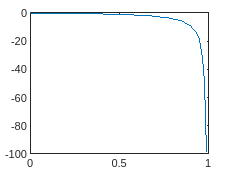



clear all;
D = linspace(0, 0.99, 100);
for i = 1:length(D)
    y(i) = (-D(i)/(1-D(i)));
end
plot(D, y)